clear
clc
uiimport('StormEvents_2013.csv')
pause
ev=StormEvents2013

ev = 59985×23 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                   

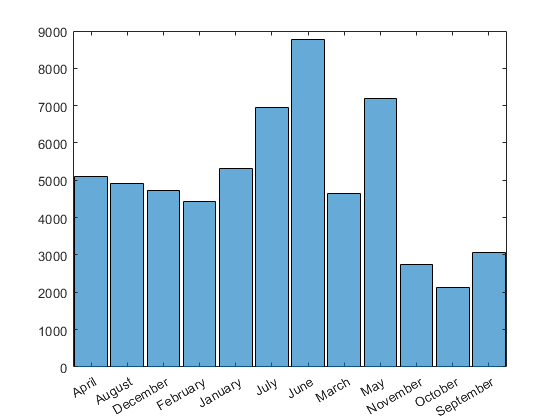

clear StormEvents2013
histogram(ev.Month);

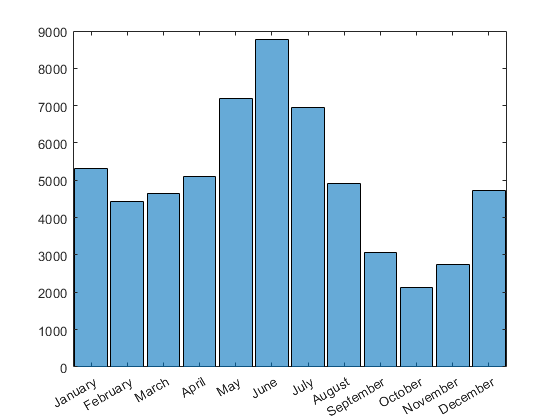

mo=["January","February","March","April","May","June","July","August","September","October","November","December"];
ev.Month=reordercats(ev.Month,mo);
histogram(ev.Month)

ev1= ev(ev.Month == 'June',:)

ev1 = 8760×23 table
    EpisodeID     Event_ID      State      Year    Month       Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                           

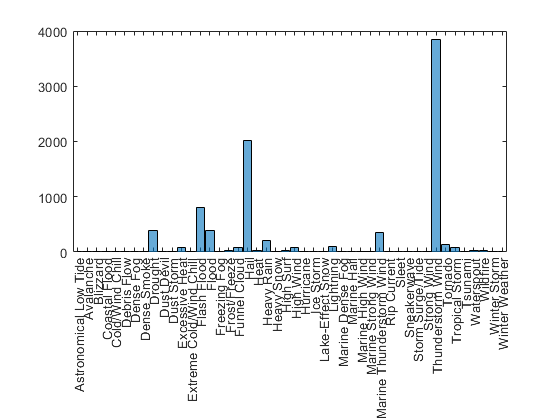

histogram(ev1.Event_Type)

ev1.Event_Type = removecats(ev1.Event_Type,{'Astronomical Low Tide','Avalanche','Extreme Cold/Wind Chill','Blizzard','Coastal Flood','Cold/Wind Chill','Dense Smoke','Freezing Fog','Heavy Snow','Hurricane','Lake-Effect Snow','Ice Storm','Marine High Wind','Marine Strong Wind','Sleet','Winter Storm','Winter Weather'})

ev1 = 8760×23 table
    EpisodeID     Event_ID      State      Year    Month       Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                           

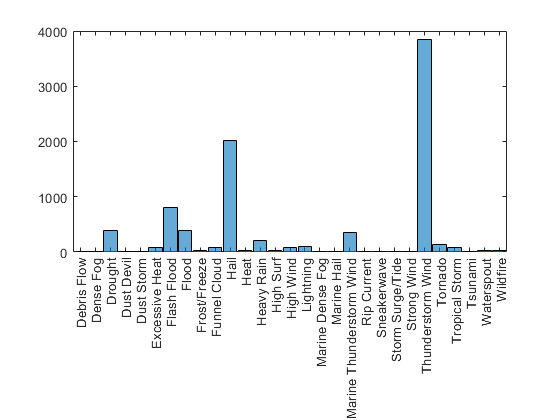

histogram(ev1.Event_Type)

ev1.Event_Type = addcats(ev1.Event_Type,{'<New Category>'});
ev1.Event_Type = renamecats(ev1.Event_Type,'<New Category>','Marine Events');
ev1.Event_Type = mergecats(ev1.Event_Type,{'Marine Events','Marine Dense Fog','Marine Hail','Marine Thunderstorm Wind','High Surf','Waterspout'})

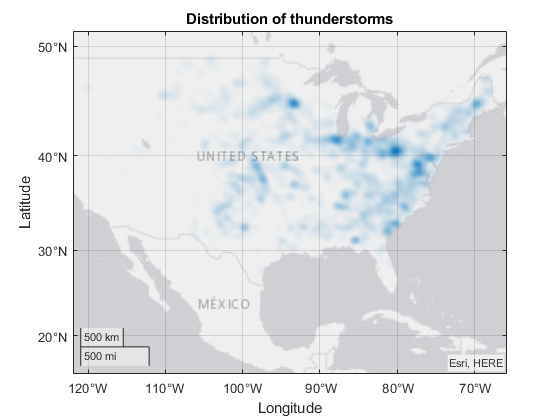

tope=ev1(ev1.Event_Type=='Thunderstorm Wind',:);
geodensityplot(tope.Begin_Lat,tope.Begin_Lon)
geolimits('auto')
title('Distribution of thunderstorms')

ev1.Property_Cost(ismissing(ev1.Property_Cost))=0;
ev1.Crop_Cost(ismissing(ev1.Crop_Cost))=0;
ev1.Total_Cost=ev1.Property_Cost+ev1.Crop_Cost

ev1 = 8760×24 table
    EpisodeID     Event_ID      State      Year    Month       Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                           

cost=mean(ev1.Total_Cost)

cost = 1.6152e+05

evcost=groupsummary(ev1,"Event_Type") 

evcost = 29×2 table
      Event_Type      GroupCount
    ______________    __________

    Debris Flow             1   
    Dense Fog               2   
    Drought               392   
    Dust Devil              1   
    Dust Storm              8   
    Excessive Heat         80   
    Flash Flood           812   
    Flood                 393   
    Frost/Freeze           33   
    Funnel Cloud           84   
    Hail                 2025   
    Heat                   31   
    Heavy Rain            209   
    High Surf              27   
    High Wind              75   
    Lightning              92   


evcostp=groupsummary(ev1,"Event_Type",["mean","std"],"Total_Cost");

evcostp = 29×4 table
      Event_Type      GroupCount    mean_Total_Cost    std_Total_Cost
    ______________    __________    _______________    ______________

    Debris Flow             1              10000                  0  
    Dense Fog               2                  0                  0  
    Drought               392         1.2171e+06         6.4285e+06  
    Dust Devil              1                  0                  0  
    Dust Storm              8          1.875e+05         5.3033e+05  
    Excessive Heat         80                625             3927.7  
    Flash Flood           812         1.5065e+05         1.2616e+06  
    Flood                 393              56207          3.284e+05  
    Frost/Freeze           33                  0                  0  
    Funnel Cloud           84                  0                  0  
  

%evcostp(ismissing())=0
   
